# Practice Finding Peaks

clear;
load sunspot.dat
yr = sunspot(:,1);
sunspotNumber = sunspot(:,2);

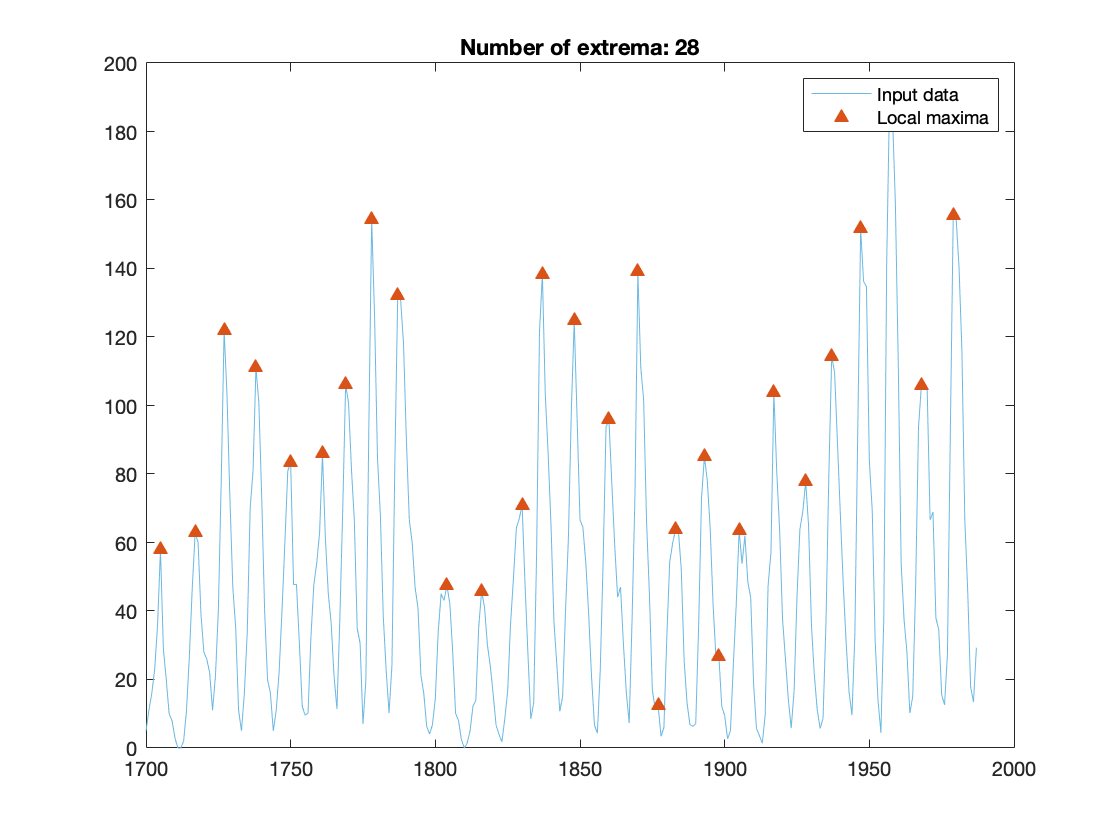

% Find local maxima
maxIndices = islocalmax(sunspotNumber,'MinSeparation',5,'SamplePoints',yr);

% Display results
clf
plot(yr,sunspotNumber,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(yr(maxIndices),sunspotNumber(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices))])
hold off
legend

peakDiff = diff(yr(maxIndices));
F0 = mean(peakDiff)

F0 = 10.1481

# Quiz 5: Domain-Specific Feature Engineering

load sensorlog_20190714.mat Acceleration
Acceleration = retime(Acceleration,'regular','linear','SampleRate',50)

Acceleration = 3478×3 timetable
           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    14-Jul-2019 18:50:47.460    -2.3973    4.8675    8.5014
    14-Jul-2019 18:50:47.480    -2.3727    4.7323    9.2834
    14-Jul-2019 18:50:47.500    -1.8247    4.5513    8.6581
    14-Jul-2019 18:50:47.520     -1.636    4.5655    8.2311
    14-Jul-2019 18:50:47.540    -1.6917    4.6177    8.2586
    14-Jul-2019 18:50:47.560    -1.9529    4.7121    8.0291
    14-Jul-2019 18:50:47.580    -1.8343    4.7253    8.0047
    14-Jul-2019 18:50:47.600    -1.4495    4.5471     8.213
    14-Jul-2019 18:50:47.620    -1.2811    4.4144    8.6894
    14-Jul

jogSignal = detrend(Acceleration.Y(Acceleration.Timestamp > "14-Jul-2019 18:51:32"))

jogSignal =    -1.7021
   -1.8624
   -2.0644
   -2.3310
   -2.5720
   -2.7085
   -2.4883
   -2.0819
   -1.8950
   -1.9201


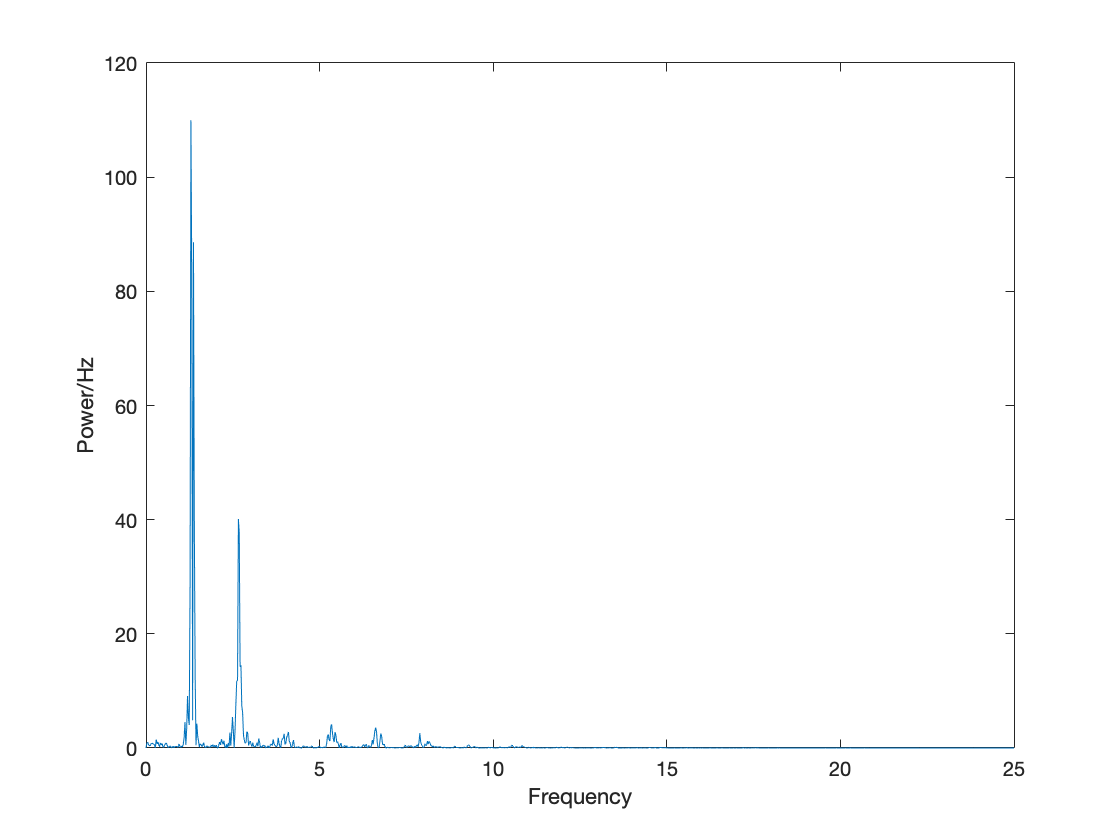


[jogSpectrum,jogFrequencies] = periodogram(jogSignal,[],[],50);

plot(jogFrequencies,jogSpectrum)
xlabel("Frequency")
ylabel("Power/Hz")

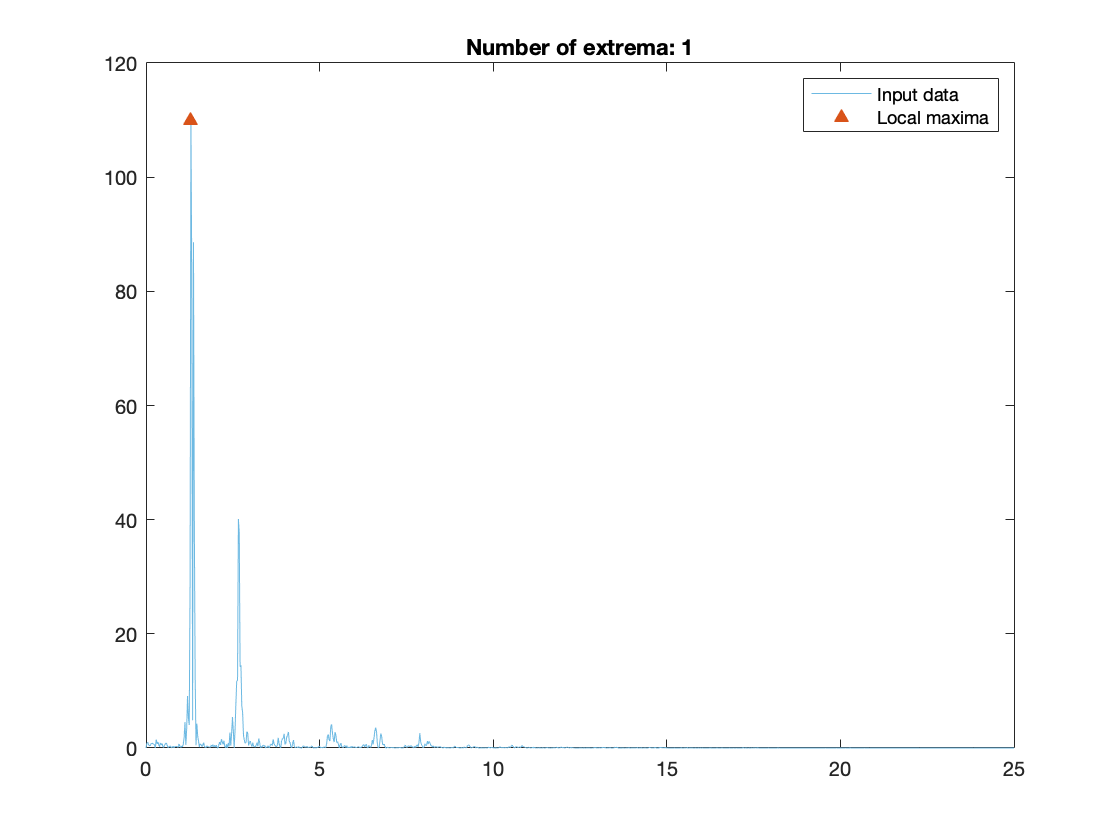

% Find local maxima
maxIndices2 = islocalmax(jogSpectrum,'MinProminence',100,...
    'SamplePoints',jogFrequencies);

% Display results
clf
plot(jogFrequencies,jogSpectrum,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on

% Plot local maxima
plot(jogFrequencies(maxIndices2),jogSpectrum(maxIndices2),'^',...
    'Color',[217 83 25]/255,'MarkerFaceColor',[217 83 25]/255,...
    'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices2))])
hold off
legend

disp(jogFrequencies(maxIndices2))

    1.2939



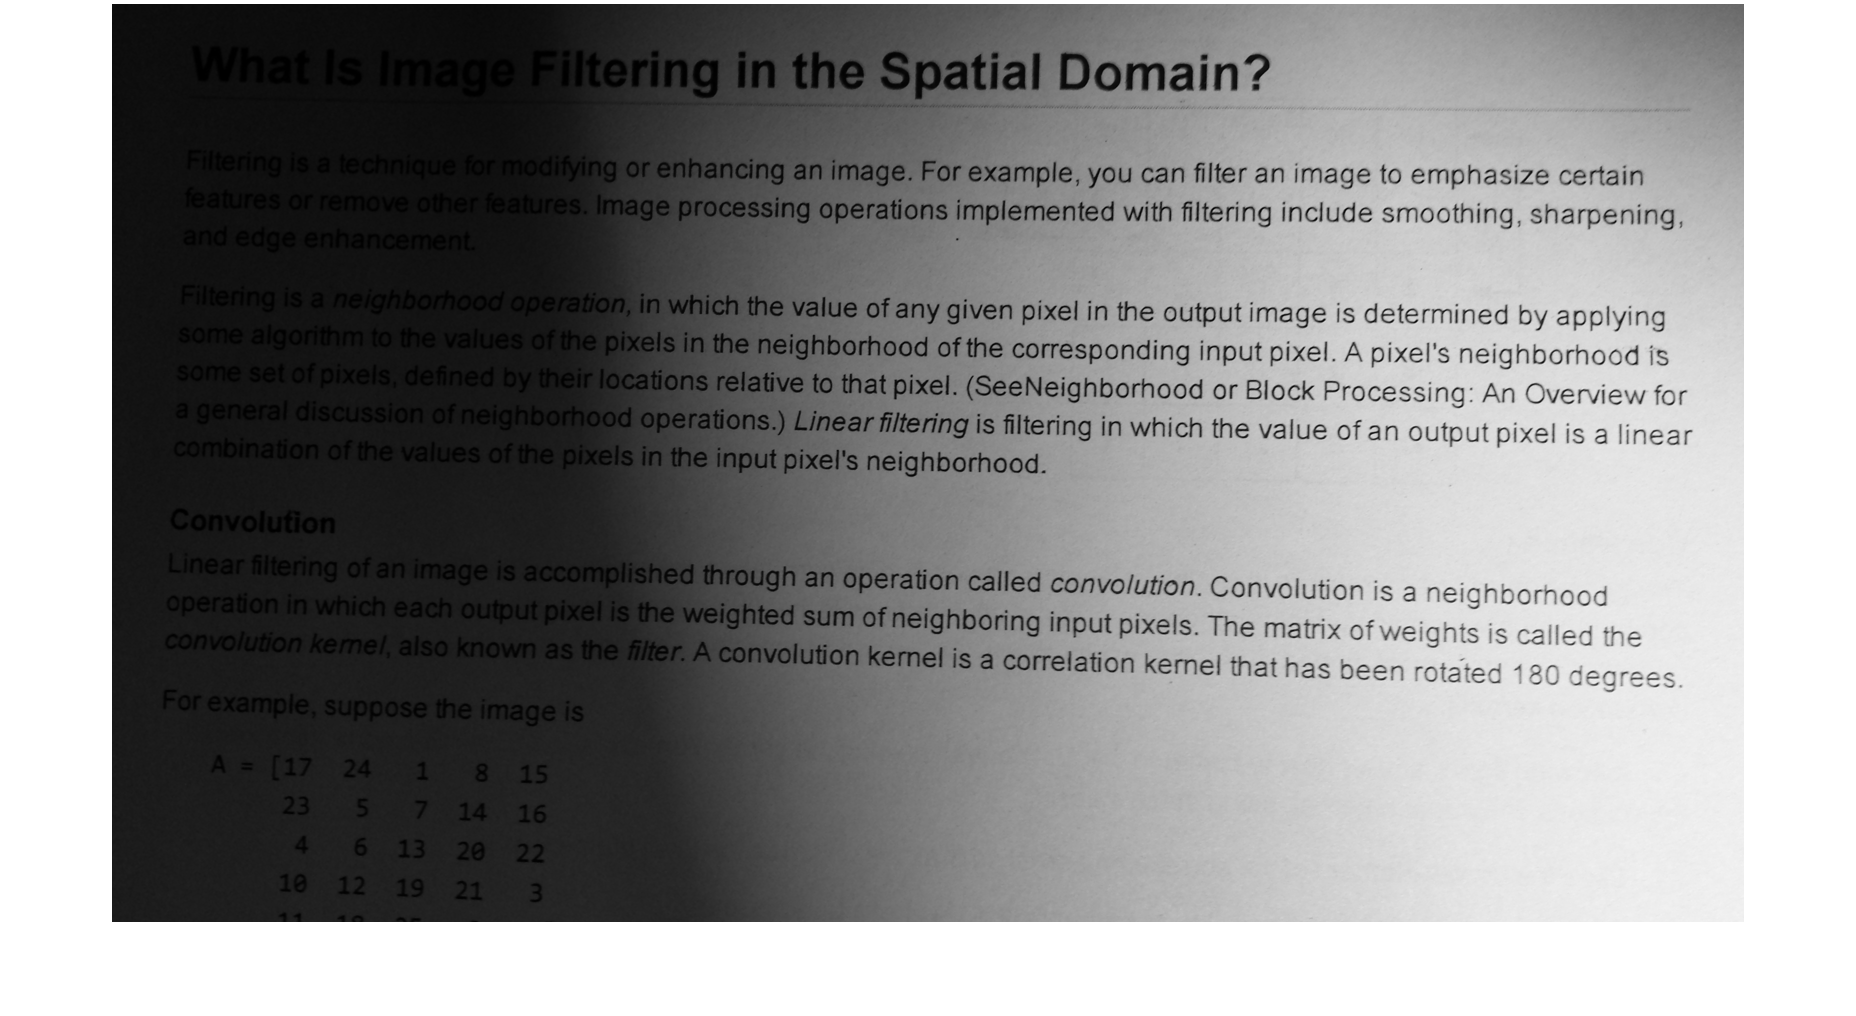

clear;
textImage = imread("printedtext.png");
imshow(textImage)

BW = segmentTextImage(textImage);
ocrOutput = ocr(BW);
ocrText = string(ocrOutput.Text)

ocrText =     " 
     
     What is Image Filtering in the Spatial Domain?
     
     Filtering is a technique formodliying or enhancing an image. For example, you can ﬁlter an Image to emphasize certain
     features or remove other feamres. Image processing operations implemented with ﬁltering include smoothing, sharpening,
     
     and edge enhancement
     Filtering is a neighborhoodoparaﬁon, in which the value ofany given pixel in the output image is determined by applying
     some algorithm to the values oflhe pixels in the neighborhood of the corresponding input pixel. A pixe|'s neighborhood is
     
     some set ofpixels. deﬁned by their locations relative to that pixel‘ (SeeNeighborhood or Block Processing: An Overview for
     a general discussion of neighborhood operations.) L/near ﬁltering is ﬁltering in which the value ofan output pixel is a linear
     
     combination of the values of the pixels in the input pixel‘s neighborhood.
     
     Convolution
     /ut/‘on.

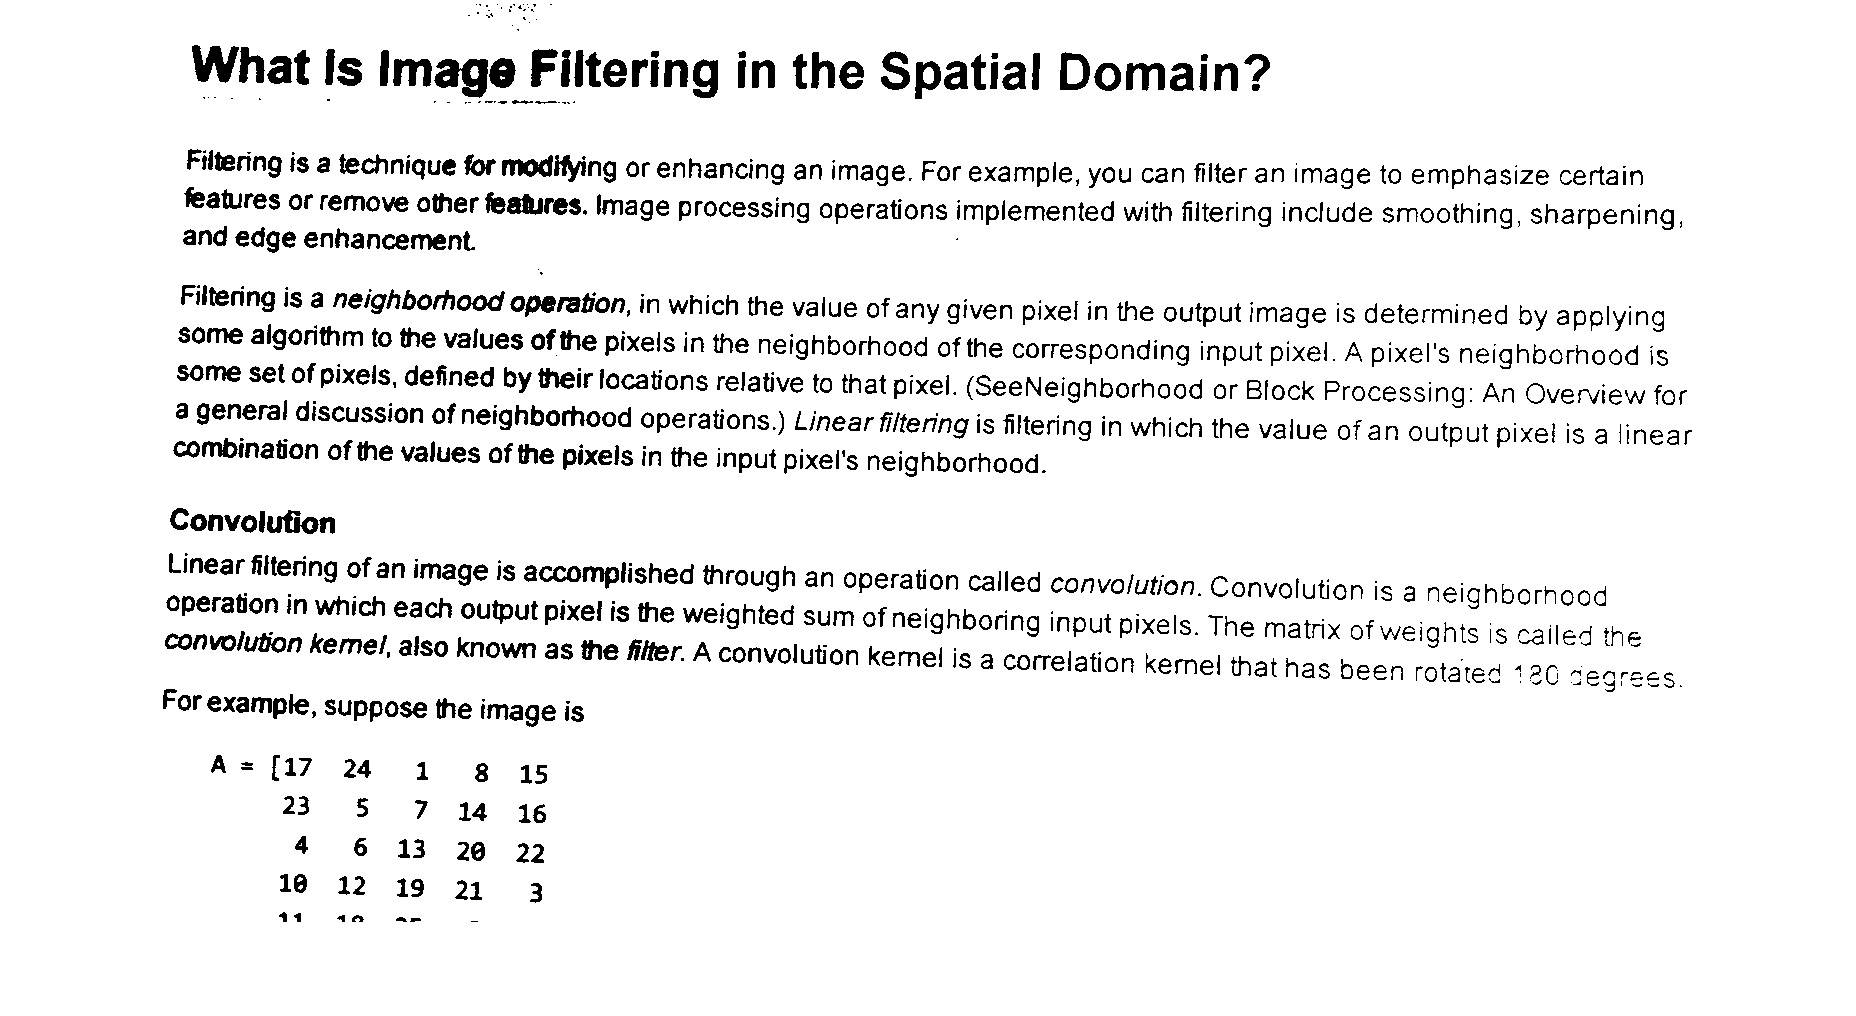

imshow(BW)

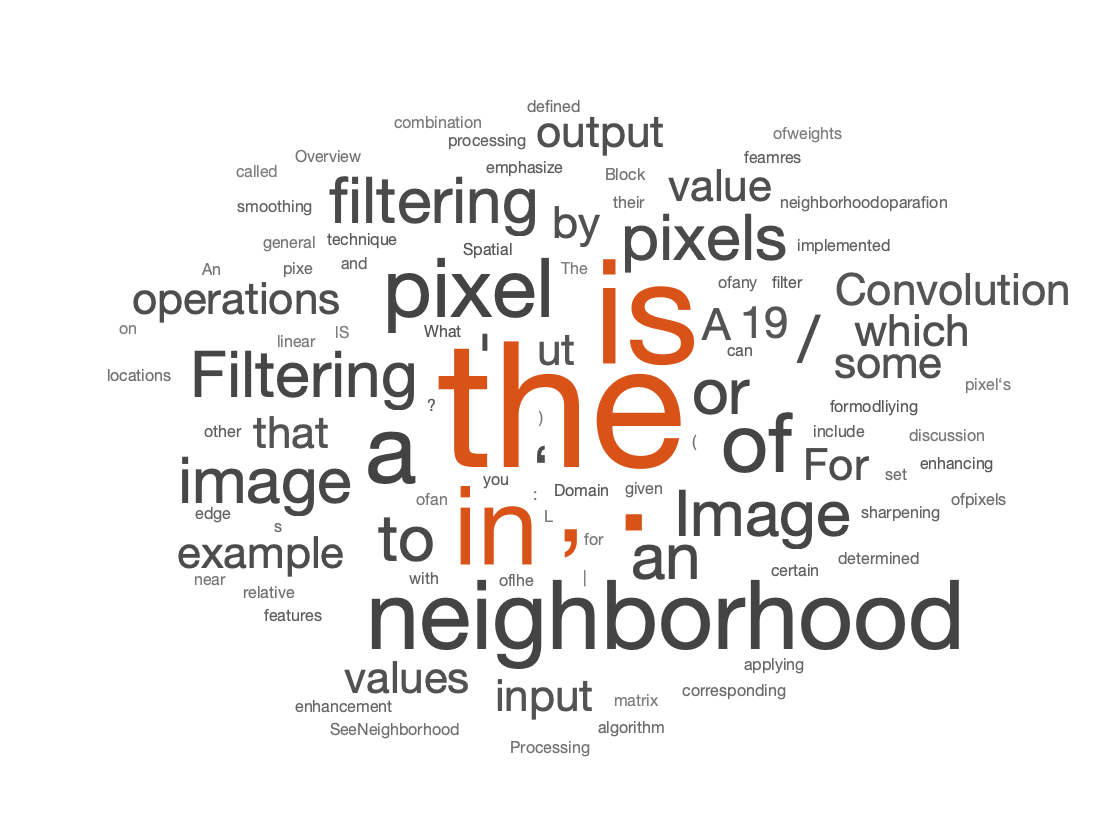

tokenizedText = tokenizedDocument(ocrText);
figure;
wordcloud(tokenizedText);

wordBagText = bagOfWords(tokenizedText)

wordBagText =   bagOfWords with properties:

          Counts: [1×132 double]
      Vocabulary: [1×132 string]
        NumWords: 132
    NumDocuments: 1


top5words = topkwords(wordBagText,5)

top5words = 5×2 table
    Word     Count
    _____    _____

    "the"     12  
    "is"       9  
    "."        9  
    "in"       6  
    ","        6  


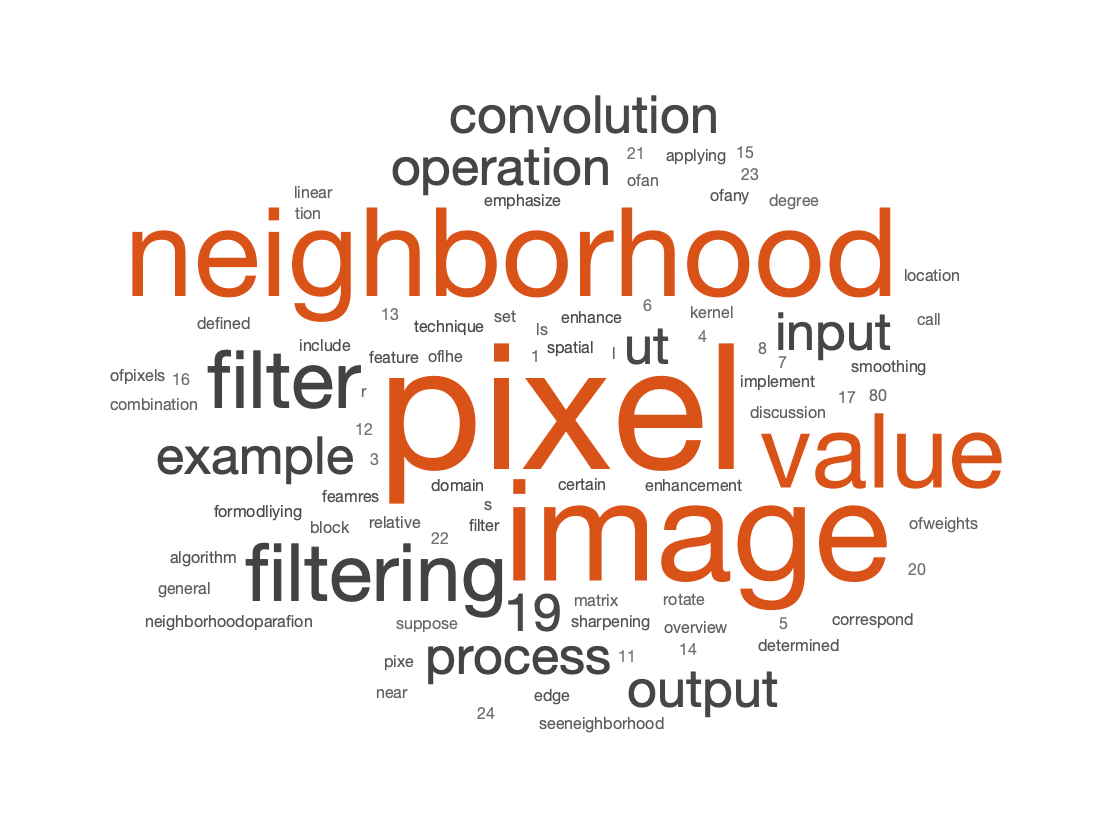

tokenizedText = erasePunctuation(tokenizedText);
tokenizedText = removeStopWords(tokenizedText);
tokenizedText = addPartOfSpeechDetails(tokenizedText);
tokenizedText = normalizeWords(tokenizedText,'Style','lemma');

figure;
wordcloud(tokenizedText);

wordBagText = bagOfWords(tokenizedText)

wordBagText =   bagOfWords with properties:

          Counts: [6 3 1 1 1 1 1 2 1 1 1 1 1 1 2 2 1 3 1 1 1 1 1 1 4 1 8 2 1 1 1 1 5 1 2 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 2 2 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 2 1 1 1 1]
      Vocabulary: [1×85 string]
        NumWords: 85
    NumDocuments: 1


top5words = topkwords(wordBagText,5)

top5words = 5×2 table
         Word         Count
    ______________    _____

    "pixel"             8  
    "image"             6  
    "neighborhood"      5  
    "value"             4  
    "filter"            3  
